
 0% ECoG 128 channels correlation

ans = 0

load("D:\Physiological Data\兔子ECoG256道\DA\1_210530_200459.mat")

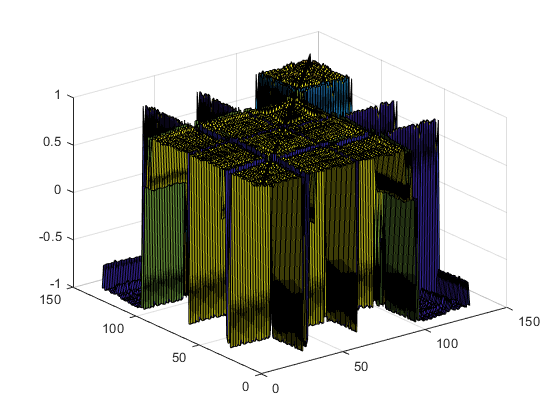

resultMatrix1 = corrcoef(amplifier_data_N');
surf(1:128, 1:128, resultMatrix1)

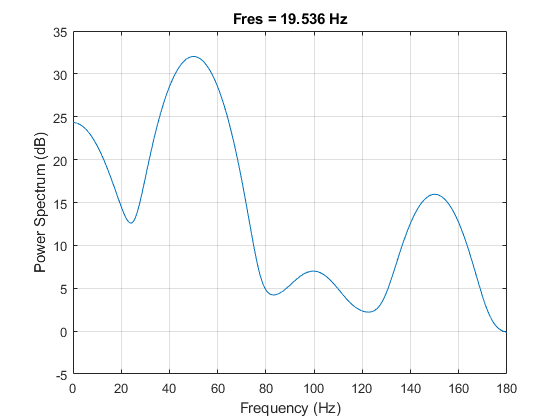

% Power v.s. Frequency
channel1 = array2timetable(amplifier_data_N(1,:)',"SampleRate", sample_rate);
channel1.Properties.VariableNames = ["Signal"];
pspectrum(channel1, "FrequencyLimits",[0 180])
hold off

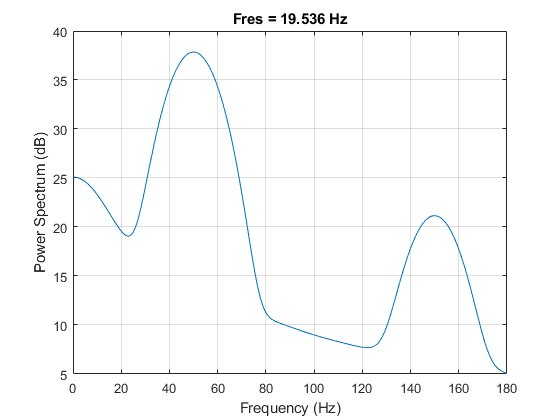

channel110 = array2timetable(amplifier_data_N(110,:)',"SampleRate", sample_rate);
channel110.Properties.VariableNames = ["Signal"];
pspectrum(channel110, "FrequencyLimits",[0 180])
hold off

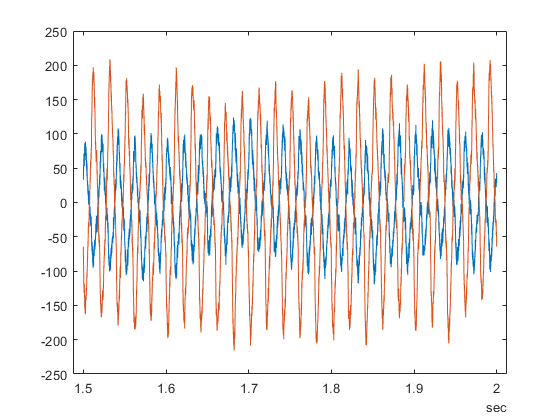

% closer look at the spiking in time-domain
plot(channel1.Time(30000:40000), channel1.Signal(30000:40000));
hold on
plot(channel110.Time(30000:40000), channel110.Signal(30000:40000));
hold off

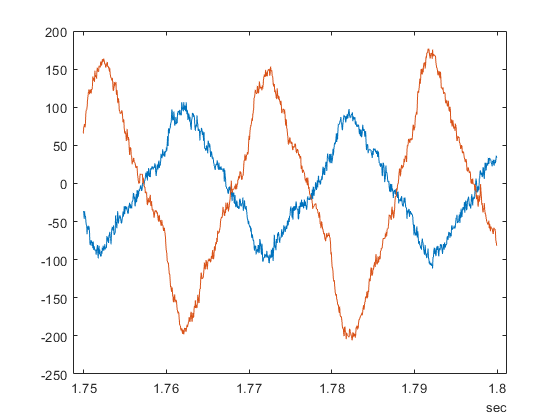

plot(channel1.Time(35000:36000), channel1.Signal(35000:36000));
hold on
plot(channel110.Time(35000:36000), channel110.Signal(35000:36000));
hold off

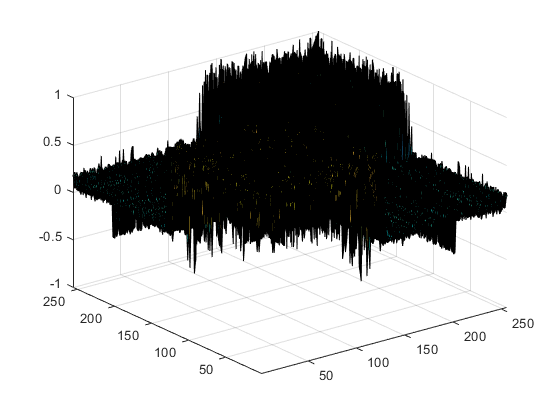

% compare correlation among 256 channels at different times
% 3 mins in total, each file contains 1 min data
load('D:\Physiological Data\兔子刺入式256道\DA\1_210506_001254.mat')
d1 = amplifier_data_N;
resultMatrix2 = corrcoef(amplifier_data_N');
surf(1:256, 1:256, resultMatrix2)
xlim([1 256])
ylim([1 256])
hold off

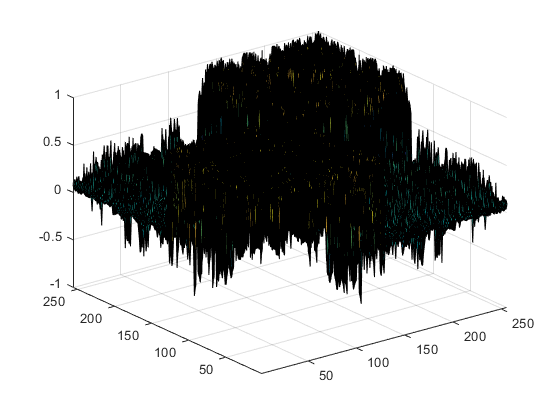

load('D:\Physiological Data\兔子刺入式256道\DA\1_210506_001354.mat')
d2 = amplifier_data_N;
resultMatrix3 = corrcoef(amplifier_data_N');
surf(1:256, 1:256, resultMatrix3)
xlim([1 256])
ylim([1 256])
hold off

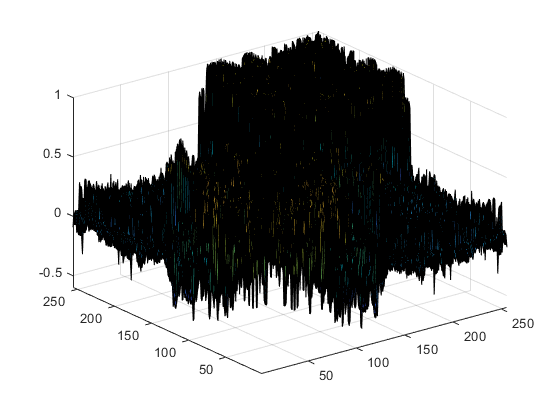

load('D:\Physiological Data\兔子刺入式256道\DA\1_210506_001454.mat')
d3 = amplifier_data_N;
resultMatrix4 = corrcoef(amplifier_data_N');
surf(1:256, 1:256, resultMatrix4)
xlim([1 256])
ylim([1 256])
hold off

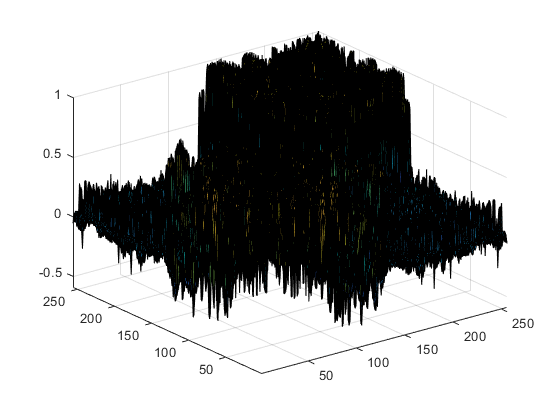

data_3mins = [d1 d2 d3];
resultMatrix5 = corrcoef(data_3mins');
surf(1:256, 1:256, resultMatrix5)
xlim([1 256])
ylim([1 256])
hold off

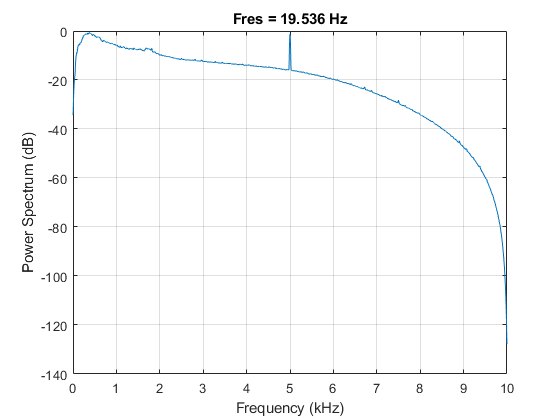

load('D:\Physiological Data\兔子刺入式256道\DA\SinCh\Channel_1.mat')
chan1_HBP = array2timetable(data_ch_HBP, "SampleRate", sample_rate);
chan1_LBP = array2timetable(data_ch_LBP, "SampleRate", sample_rate);
chan1_NF = array2timetable(data_ch_NF', "SampleRate", sample_rate);
chan1_HBP.Properties.VariableNames = ["Signal"];
chan1_LBP.Properties.VariableNames = ["Signal"];
chan1_NF.Properties.VariableNames = ["Signal"];
pspectrum(chan1_HBP)
hold off

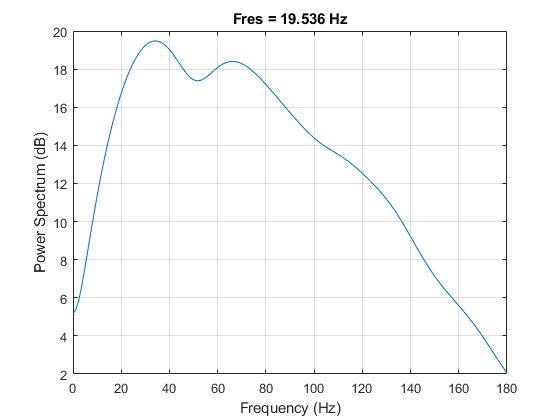

pspectrum(chan1_LBP, "FrequencyLimits", [0 180])
hold off

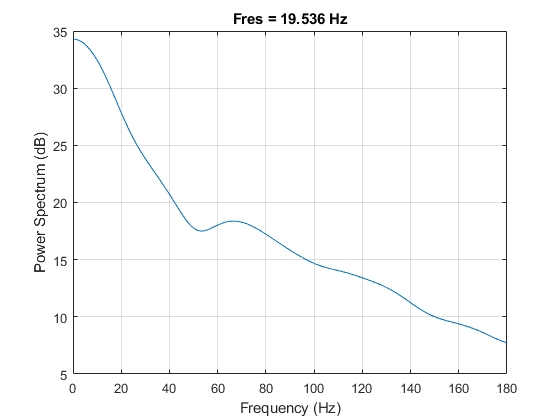

pspectrum(chan1_NF, "FrequencyLimits", [0 180])
hold off

Folder = "D:\Physiological Data\兔子刺入式256道\DA\SinCh"

Folder = "D:\Physiological Data\兔子刺入式256道\DA\SinCh"

DirList = dir(fullfile(Folder, '*.mat'));

for k = 1:length(DirList)
    DirList(k).name;
  % Data{k} = load(fullfile(Folder, DirList(k).name));
end

% sort files
fileTable = dir(fullfile(Folder, '*.mat'));
fileindex = zeros(length(fileTable), 1);
for k = 1:length(fileTable)
    fileindex(k, 1) = sscanf(fileTable(k).name, "Channel_%d.mat");
end
fileTable = struct2table(fileTable);
fileTable.index = fileindex;
fileTable = sortrows(fileTable, "index");

% merge HBP&LBP&NF signals in each channel
l = length(fileTable.index);
all_HBP = zeros(3601920,l);
all_LBP = zeros(3601920,l);
all_NF = zeros(3601920,l);
for i = 1:l
    load(fullfile(fileTable(i,:).folder{1}, fileTable(i,:).name{1}));
    all_HBP(:,i) = data_ch_HBP;
    all_LBP(:,i) = data_ch_LBP;
    all_NF(:,i) = data_ch_NF';
end

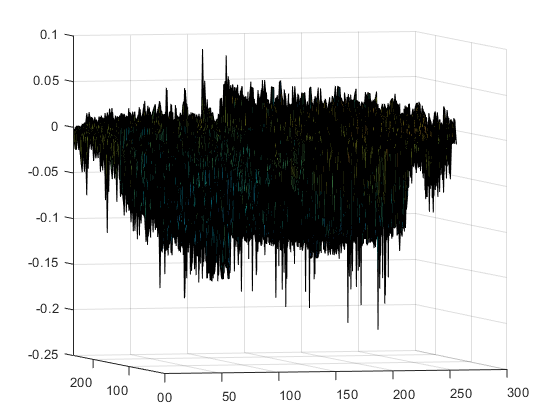

% aMatrix = corrcoef([all_LBP , all_HBP]);
% surf(1:256, 1:256, aMatrix(1:256, 257:end));
% hold off

 all_LBP_downsampled = all_LBP(1:20:end,:); % down sampling the LBP signal
 downsampled_sampling_rate = 1000;

resultMatrix_HBP = corrcoef(all_HBP);

surf(1:256, 1:256, resultMatrix_HBP)

hold off

resultMatrix_LBP = corrcoef(all_LBP);

surf(1:256, 1:256, resultMatrix_LBP)

hold off

resultMatrix_NF = corrcoef(all_NF);

surf(1:256, 1:256, resultMatrix_NF)

hold off

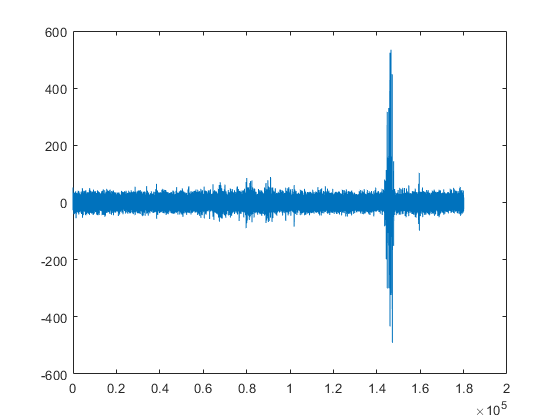

plot(all_LBP_downsampled(:,1)');
hold off

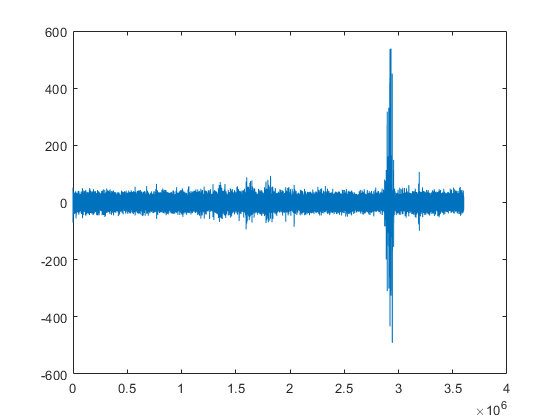

plot(all_LBP(:,1)');
hold off

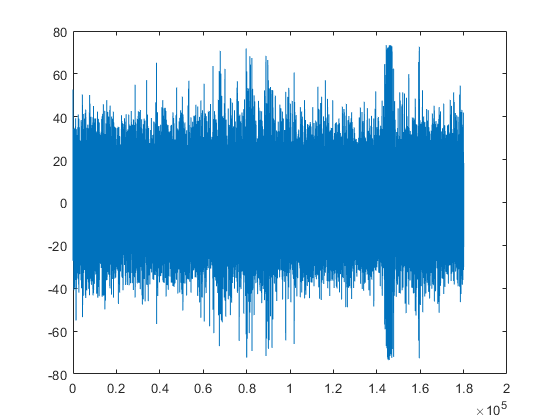

all_LBP_i = all_LBP_downsampled;
for i=1:8
    LBP_mean = mean(all_LBP_i);
    LBP_std = std(all_LBP_i);
    z_score = 5;
    LBP_high_outliers = LBP_mean + z_score*LBP_std;
    LBP_low_outliers = LBP_mean - z_score*LBP_std;
    LBP_high_noises = all_LBP_i >= LBP_high_outliers;
    LBP_low_noises = all_LBP_i <= LBP_low_outliers;
    LBP_noises = LBP_low_noises + LBP_high_noises;
    all_LBP_cleared = all_LBP_i .* ~LBP_noises;
    plot(all_LBP_cleared(:,1)');
    hold off
    all_LBP_i = all_LBP_cleared;
end

all_LBP_downsampled = all_LBP_cleared;


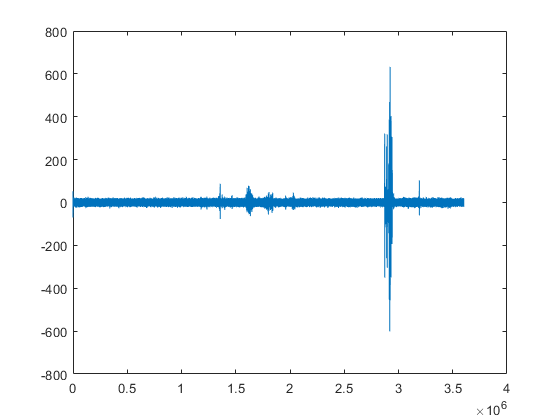

plot(all_HBP(:,1)');
hold off

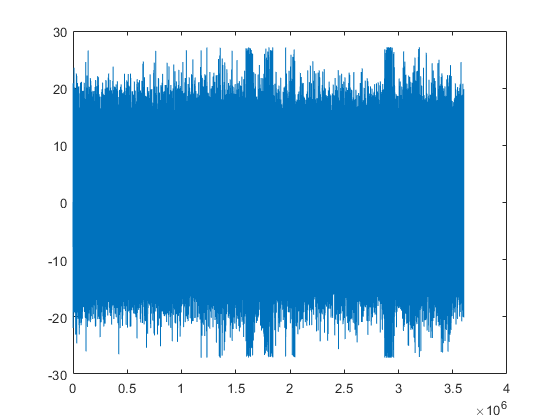

all_HBP_i = all_HBP;
for i=1:8
    LBP_mean = mean(all_HBP_i);
    HBP_std = std(all_HBP_i);
    z_score = 5;
    LBP_high_outliers = LBP_mean + z_score*HBP_std;
    LBP_low_outliers = LBP_mean - z_score*HBP_std;
    LBP_high_noises = all_HBP_i >= LBP_high_outliers;
    HBP_low_noises = all_HBP_i <= LBP_low_outliers;
    LBP_noises = HBP_low_noises + LBP_high_noises;
    all_HBP_cleared = all_HBP_i .* ~LBP_noises;
    plot(all_HBP_cleared(:,1)');
    hold off
    all_HBP_i = all_HBP_cleared;
end

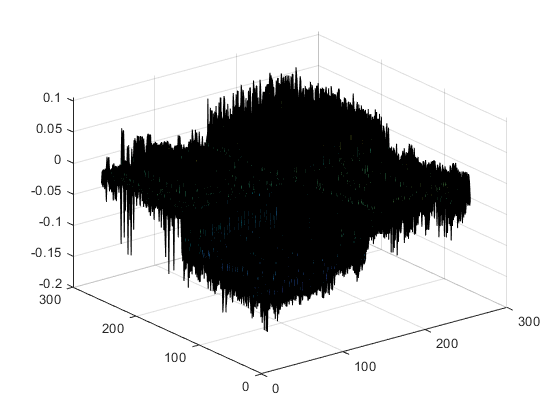

aMatrix = corrcoef([all_LBP_cleared , all_HBP_cleared(1:20:end,:)]);
surf(1:256, 1:256, aMatrix(1:256, 257:end));
hold off

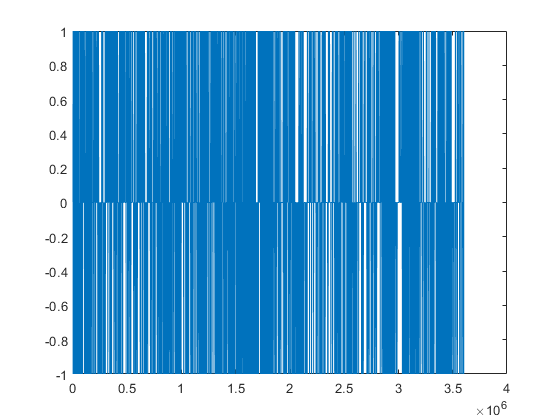

z_score = 3.5 ;
all_HBP_cleared_mean = mean(all_HBP_cleared);
all_HBP_cleared_std = std(all_HBP_cleared);
HBP_high_thr = all_HBP_cleared_mean + z_score*all_HBP_cleared_std;
HBP_low_thr = all_HBP_cleared_mean - z_score*all_HBP_cleared_std;
HBP_spikings = (all_HBP_cleared >= HBP_high_thr) - (all_HBP_cleared <= HBP_low_thr);
plot(HBP_spikings(:,1)')
hold off

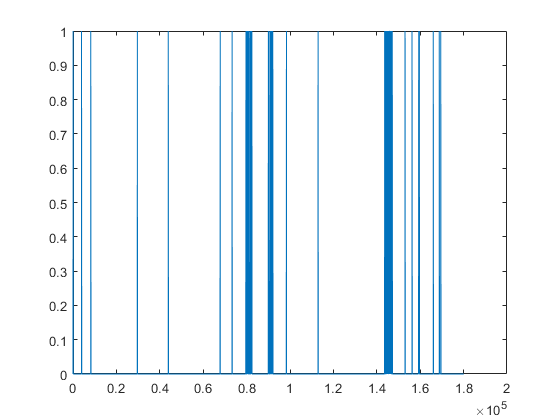

HBP_size = size(HBP_spikings);
j = 1;
HBP_spikings_downsampled = zeros(HBP_size(1)/20, HBP_size(2));
for i = 1:20:HBP_size(1)
    for k=1:256
%         if sum(HBP_spikings(i:i+19,k)==1) >= sum(HBP_spikings(i:i+19,k)==-1)
%             HBP_spikings_downsampled(j,k) = sum(HBP_spikings(i:i+19,k)==1);
%         else
%             HBP_spikings_downsampled(j,k) = sum(HBP_spikings(i:i+19,k)==-1);
%         end
        HBP_spikings_downsampled(j,k) = any(HBP_spikings(i:i+19,k)==1) & any(HBP_spikings(i:i+19,k)==-1);
    end
    j = j+1;
end
plot(HBP_spikings_downsampled(:,1)')
hold off

size(HBP_spikings_downsampled)

ans =       180096         256


% pspectrum(HBP_spikings_downsampled)

size(all_LBP_downsampled)

ans =       180096         256


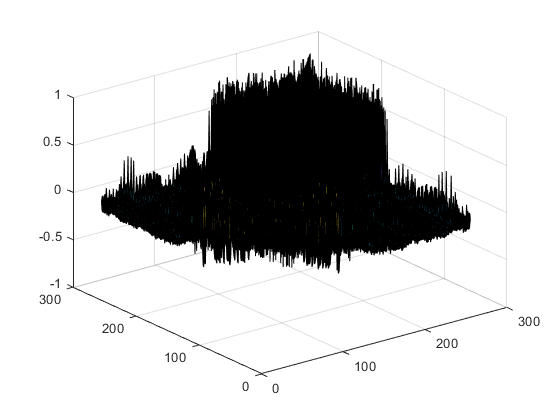

resultMatrix_LBP_ds = corrcoef(all_LBP_downsampled);
surf(1:256, 1:256, resultMatrix_LBP_ds)
hold off

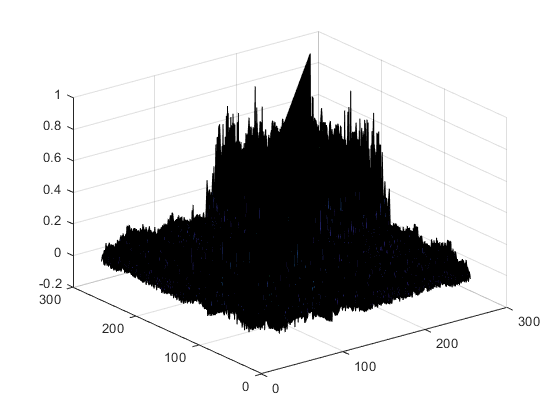

resultMatrix_HBP_ds = corrcoef(HBP_spikings_downsampled);
surf(1:256, 1:256, resultMatrix_HBP_ds)
hold off

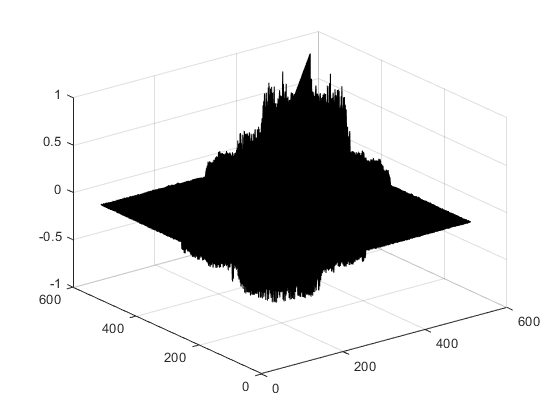

resultMatrix_combined_ds = corrcoef([all_LBP_downsampled, HBP_spikings_downsampled]);
surf(1:256*2, 1:256*2, resultMatrix_combined_ds)
hold off 

size(resultMatrix_combined_ds)

ans =    512   512


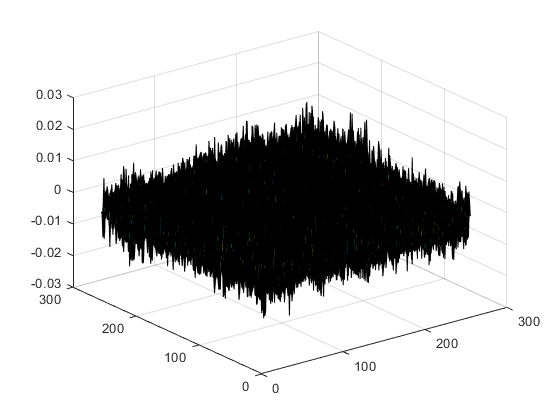

surf(1:256, 1:256, resultMatrix_combined_ds(1:256, 257:end))
hold off

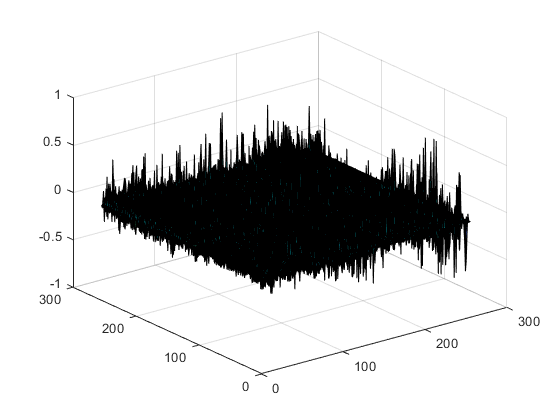

PCA_LBP = pca(all_LBP_downsampled);
surf(1:256, 1:256, PCA_LBP);
hold off

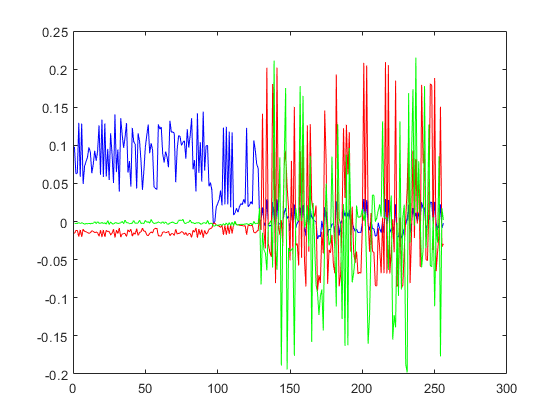

plot(PCA_LBP(:,1)', 'color', 'b');
hold on
plot(PCA_LBP(:,2)', 'color', 'r');
hold on
plot(PCA_LBP(:,3)', 'color', 'g');
hold off

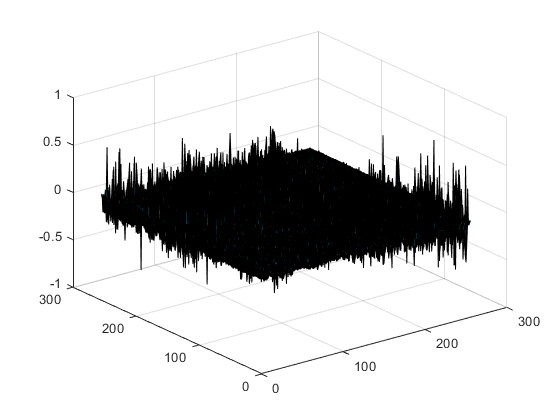

PCA_HBP = pca(HBP_spikings_downsampled);
surf(1:256, 1:256, PCA_HBP);
hold off

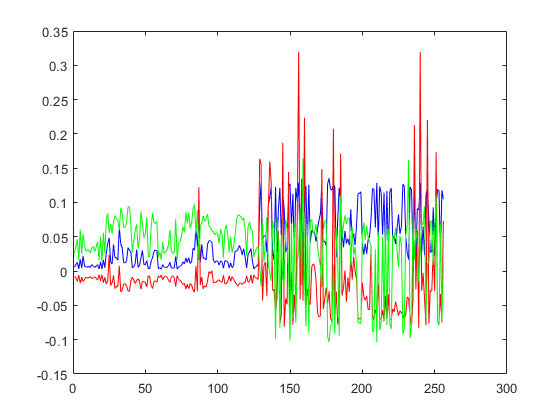

plot(PCA_HBP(:,1)', 'color', 'b');
hold on
plot(PCA_HBP(:,2)', 'color', 'r');
hold on
plot(PCA_HBP(:,3)', 'color', 'g');
hold off